# Q1a

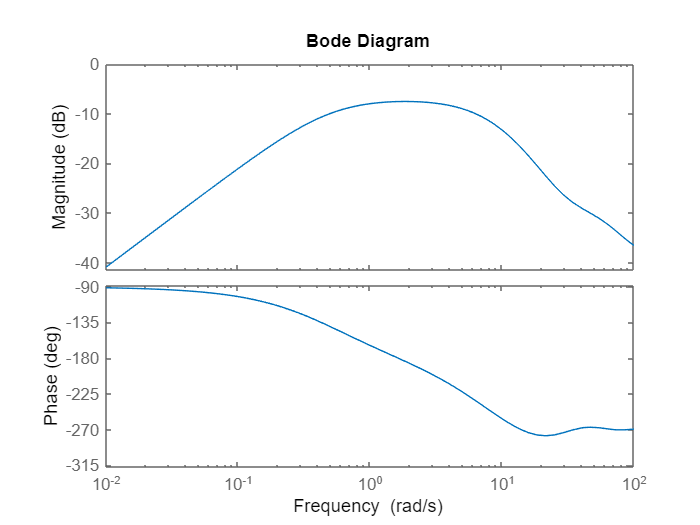

close all
clear all
clc;
s = tf('s');
G = 3*exp(-0.1*s)/(2*s+1)/(0.1*s+1)^2;
G_nom = 3/(2*s+1);
WI = G-G_nom;
bode(WI);

# Q1b

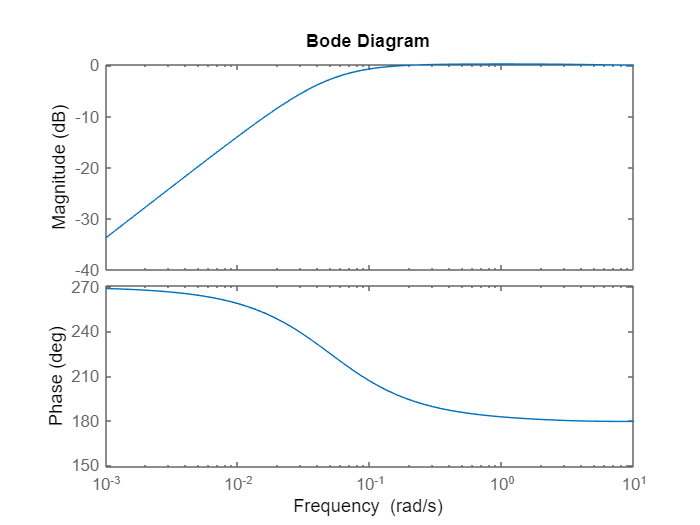

G = 10*(-0.5*s+1)/(6*s+1)/(0.2*s+1)/(20*s+1);
G_nom = 10/(6*s+1);
WI = (G-G_nom)/G_nom;
bode(WI);

# Q2a

The file contains 2 uncertain models - VCM and PZT. Use Matlab to fit a 2nd order multiplicative uncertainty weight that best approximates the uncertainty for each model. Report the final weight for each, and plot (Gp−G)/G for various perturbed plants Gp vs. the uncertainty weight for each plant.

close all
clear all
clc;
%Build uncertain atoms
wv1 = ureal('wv1',135,'Percentage',10);
wv2 = ureal('wv2',5500,'Percentage',10);
wv3 = ureal('wv3',8640,'Percentage',10);
wv41 = ureal('wv41',7300,'Percentage',10);
wv42 = ureal('wv42',7650,'Percentage',10);
dv1 = ureal('dv1',0.1,'Percentage',20);
dv2 = ureal('dv2',0.03,'Percentage',20);
dv3 = ureal('dv3',0.05,'Percentage',20);
dv41 = ureal('dv41',0.03,'Percentage',20);
dv42 = ureal('dv42',0.015,'Percentage',20);
uvcm = ultidyn('uvcm',[1,1]);
Wvcm = makeweight(1e-6,5000,3);

%Construct uncertain plant
Gv = 10;  %DC Gain
Gv1 = tf((2*pi*wv1)^2,[1 2*dv1*2*pi*wv1 (2*pi*wv1)^2]);
Gv2 = tf((2*pi*wv2)^2,[1 2*dv2*2*pi*wv2 (2*pi*wv2)^2]);
Gv3 = tf((2*pi*wv3)^2,[1 2*dv3*2*pi*wv3 (2*pi*wv3)^2]);
Gv4 = wv41^2/wv42^2*tf([1 2*dv42*2*pi*wv42 (2*pi*wv42)^2],[1 2*dv41*2*pi*wv41 (2*pi*wv41)^2]);
VCM = Gv*Gv1*Gv2*Gv3*Gv4*(1+Wvcm*uvcm);

wp1 = ureal('wp1',8460,'Percentage',10);
wp21 = ureal('wp21',5500,'Percentage',10);
wp22 = ureal('wp22',5650,'Percentage',10);
wp41 = ureal('wp41',8070,'Percentage',10);
wp42 = ureal('wp42',8250,'Percentage',10);
wp51 = ureal('wp51',10650,'Percentage',10); 
wp52 = ureal('wp52',10530,'Percentage',10); 
dp1 = ureal('dp1',0.01,'Percentage',20);
dp21 = ureal('dp21',0.03,'Percentage',20);
dp22 = ureal('dp22',0.03,'Percentage',20);
dp41 = ureal('dp41',0.015,'Percentage',20);
dp42 = ureal('dp42',0.02,'Percentage',20);
dp51 = ureal('dp51',0.01,'Percentage',20);
dp52 = ureal('dp52',0.015','Percentage',20);
upzt = ultidyn('upzt',[1,1]);
Wpzt = makeweight(1e-6,8000,3);

Gp = 0.1;  %DC gain
Gp1 = tf((2*pi*wp1)^2,[1 2*dp1*2*pi*wp1 (2*pi*wp1)^2]);
Gp2 = wp21^2/wp22^2*tf([1 2*dp22*2*pi*wp22 (2*pi*wp22)^2],[1 2*dp21*2*pi*wp21 (2*pi*wp21)^2]);
Gp3 = Gv4;  %This mode is coupled between VCM and PZT
Gp4 = wp41^2/wp42^2*tf([1 2*dp42*2*pi*wp42 (2*pi*wp42)^2],[1 2*dp41*2*pi*wp41 (2*pi*wp41)^2]);
Gp5 = wp51^2/wp52^2*tf([1 2*dp52*2*pi*wp52 (2*pi*wp52)^2],[1 2*dp51*2*pi*wp51 (2*pi*wp51)^2]);
PZT = Gp*Gp1*Gp2*Gp3*Gp4*Gp5*(1+Wpzt*upzt);

Gvec1 = usample(VCM,100);  %Create 100 Monte Carlo samples of G
[P1,info] = ucover(Gvec1,VCM.NominalValue,2);  %Find the best 2nd order multiplicative uncertainty
% P1
info.W1

ans =
 
  A = 
               x1          x2
   x1  -4.086e+05    -3.2e+05
   x2   4.141e+05   3.145e+05
 
  B = 
               u1
   x1   2.306e+04
   x2  -2.306e+04
 
  C = 
           x1      x2
   y1  -186.7  -376.1
 
  D = 
          u1
   y1  17.84
 
Continuous-time state-space model.



*ucover* is finding the uncertain plant P with 4th order multiplicative uncertainty that best fits the data it receives.  Note that Gvec *could* have come from experimental frequency response data, but here we're just using *ucover* to replace the three parametric uncertainties with a single multiplicative uncertainty.  Let's see how well it did.

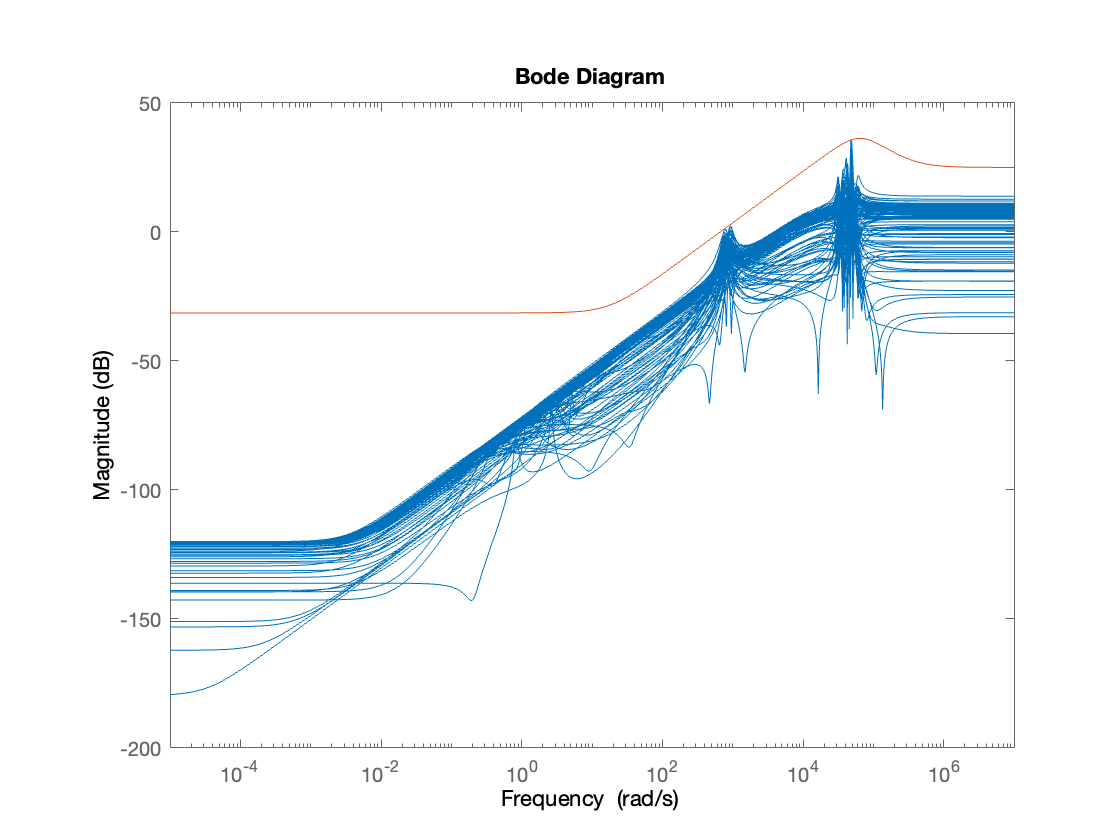

bodemag((Gvec1-VCM.NominalValue)/VCM.NominalValue,info.W1) %Gvec: 100 samples

Gvec2 = usample(PZT,100);  %Create 100 Monte Carlo samples of G
[P2,info] = ucover(Gvec2,PZT.NominalValue,2);  %Find the best 4th order multiplicative uncertainty
% P2
info.W1

ans =
 
  A = 
               x1          x2
   x1  -2.674e+05  -2.641e+05
   x2    2.72e+05   2.595e+05
 
  B = 
          u1
   x1   4213
   x2  -4213
 
  C = 
          x1     x2
   y1  -2594  -2594
 
  D = 
          u1
   y1  41.13
 
Continuous-time state-space model.



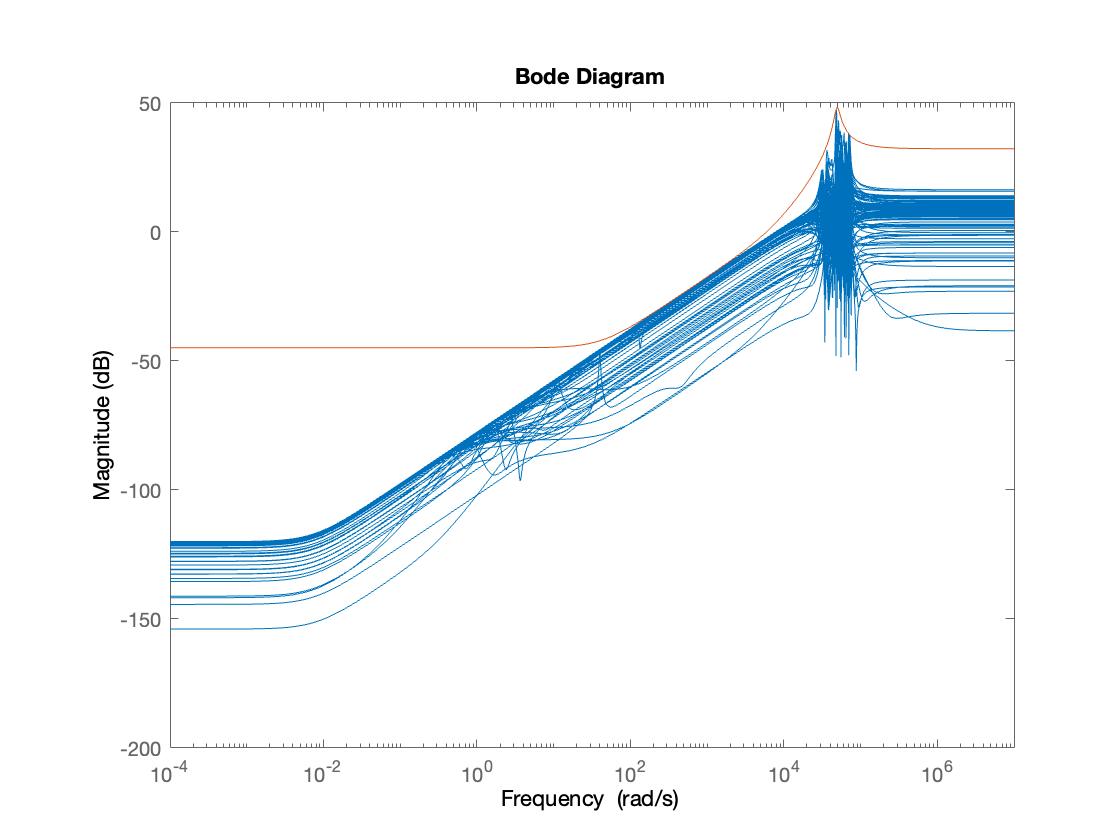

bodemag((Gvec2-PZT.NominalValue)/PZT.NominalValue,info.W1) %Gvec: 100 samples

# Q2b

Perform single stage robust controller design for the VCM plant using mixsyn. Maximize the crossover frequency such that the low frequency disturbances are rejected by a factor of 1000, the sensitivity peak is below 2, and γ < 1. A first order performance weight is fine. Compute ∥[WpS; WtT]∥∞ for your final design and plot the Bode magnitude plot of the uncertain sensitivity function vs. the performance weight.

VCMvec = usample(VCM,100);
[P_VCM,VCM_info] = ucover(VCMvec,VCM.NominalValue,2);
Wt = VCM_info.W1;  %Extract the weight
wh = 1000;  %Just guessing at this...we'll see if it fails
wl = 0;
w_try = wh;  %Just for simplicity
w_new = 1/2*(wh+wl);

while(abs(w_new-w_try)>.001)  %Stopping criterion
    w_try = w_new;
    Wp = makeweight(1000,w_try,1/2);
    [K,CL,GAM] = mixsyn(VCM,Wp,[],Wt); 
    if GAM<1%/sqrt(2)
        wl = w_try;  %We're not agressive enough
    else
        wh = w_try;  %We're too agressive
    end
    w_new = 1/2*(wh+wl);
end
S = 1/(1+VCM*K);
T = 1-S;
Svec = usample(S,100);

Now plot the achieved sensitivity functions for the uncertain plant vs the sensitivity weight.

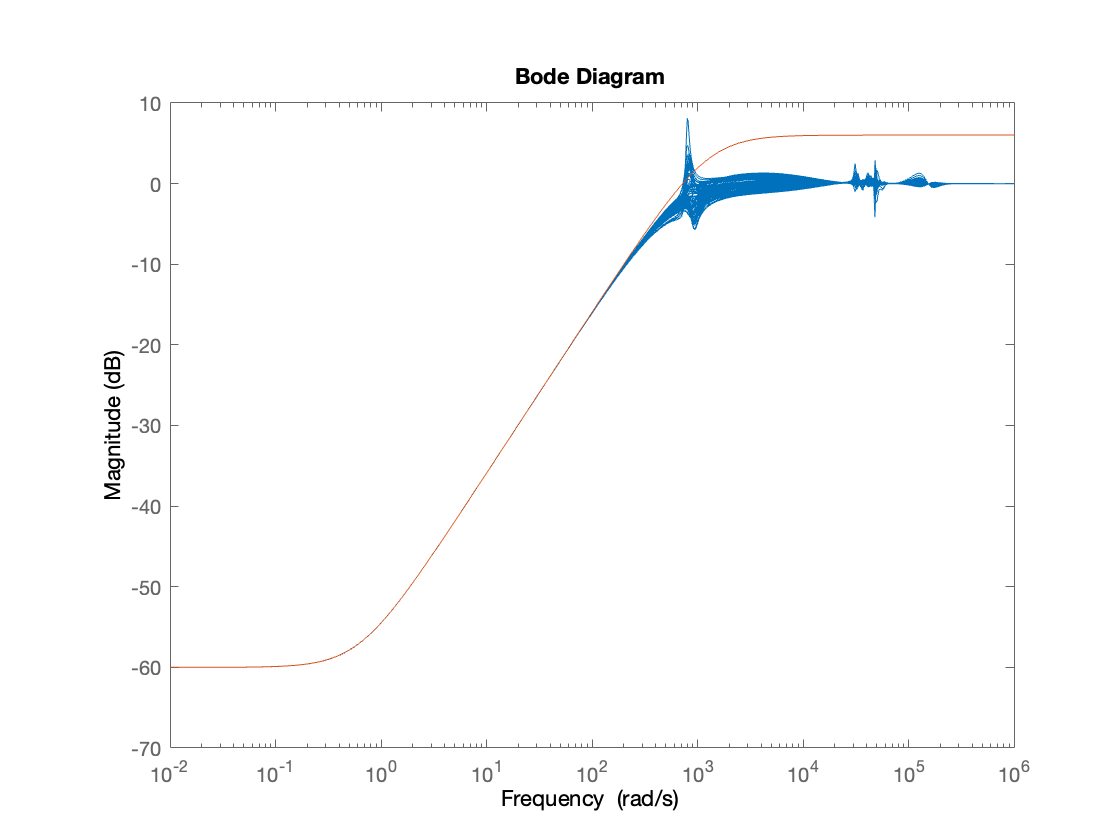

bodemag(Svec,1/Wp)

norm([Wp*S; Wt*T],"inf")

ans = 1.8857

# Q2c

Perform dual stage robust controller design for the dual stage system G = [VCM PZT]. Use the same performance criteria from part b, and again maximize the crossover frequency such that γ < 3.5. For each step of your iteration, capture γ. Plot the value of γ vs. iteration count and plot the Bode magnitude plot of the uncertain sensitivity function vs. the performance weight for the final design. Does your final design satisfy robust performance?

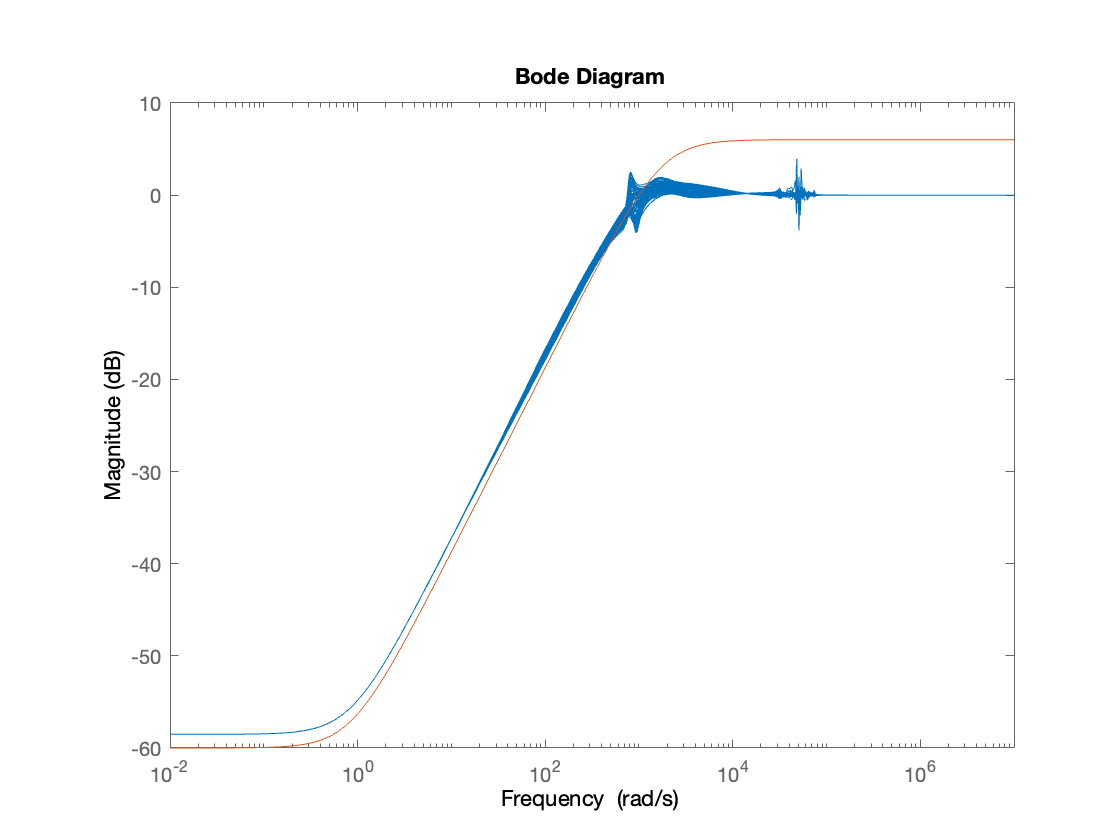

% mixsyn cannot take non-square plant so we use hinfsyn
G = [VCM PZT];
VCM_nom = VCM.NominalValue;
VCMvec = usample(VCM,100);
[P_VCM, VCM_info] = ucover(VCMvec, VCM.NominalValue, 2);
VCM_Wt = VCM_info.W1;  %Extract the weight

PZT_nom = PZT.NominalValue;
PZTvec = usample(PZT,100);
[P_PZT, PZT_info] = ucover(PZTvec, PZT.NominalValue, 2);
PZT_Wt = PZT_info.W1;  %Extract the weight

Wt = [VCM_Wt; PZT_Wt];

wh = 1000;  %Just guessing at this...we'll see if it fails
wl = 0;
w_try = wh;  %Just for simplicity
w_new = 1/2*(wh+wl);
gam_list = [];
i = 1;
while(abs(w_new-w_try)>.001)  %Stopping criterion
    w_try = w_new;
    Wp = makeweight(1000,w_try,1/2);
    systemnames = 'VCM_nom PZT_nom Wp VCM_Wt PZT_Wt'; %Block name only
    inputvar = '[d1;d2;r;u1;u2]';
    outputvar = '[VCM_Wt;PZT_Wt;Wp;VCM_nom+PZT_nom+d1+d2;r-VCM_nom-PZT_nom-d1-d2]'; %Strangely, the system outputs are just the name
    input_to_VCM_nom = '[u1]';
    input_to_PZT_nom = '[u2]';
    input_to_Wp = '[r-VCM_nom-PZT_nom-d1-d2]';
    input_to_VCM_Wt = '[u1]';
    input_to_PZT_Wt = '[u2]';
    cleanupsysic = 'yes';  %This drops all the useless variables from workspace
    P = sysic;
    [K,CL,GAM] = hinfsyn(P,1,2);
    gam_list(i) = GAM;
    if GAM<3.5 %/sqrt(2)
        wl = w_try;  %We're not agressive enough
    else
        wh = w_try;  %We're too agressive
    end
    w_new = 1/2*(wh+wl);
    i = i+1;
end
S = inv(1+G*K);
T = 1-S;
Svec = usample(S,100);
bodemag(Svec,1/Wp)

%Check Robust Perforamnce
N = lft(P,K); 
perfmarg_inf = robustperf(N);
mu_inf = 1/perfmarg_inf.LowerBound

mu_inf = 2.2209

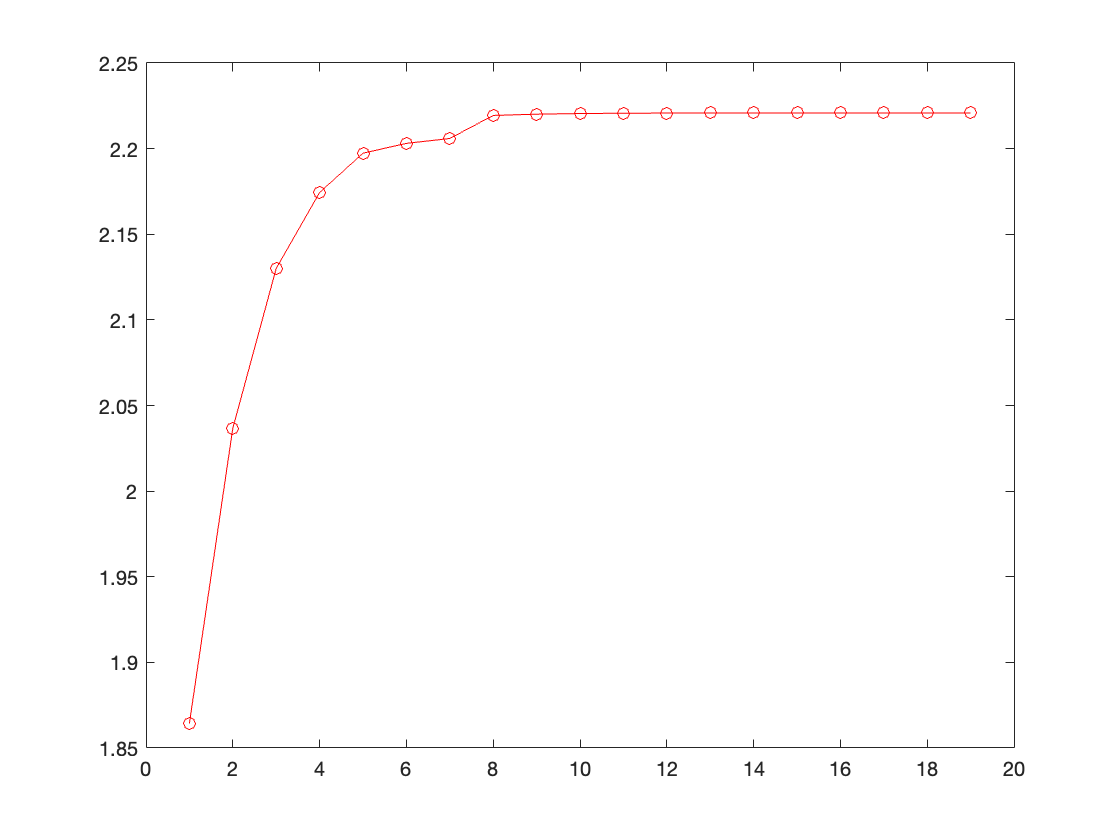

% figure
plot(1:i-1,gam_list, '-or');

# Q3a

The file responses.mat gives a vector of responses for the system. Fit a multiplicative uncertainty weight Wdel to the response. Create a Bode magnitude plot that shows the quality of your fit.

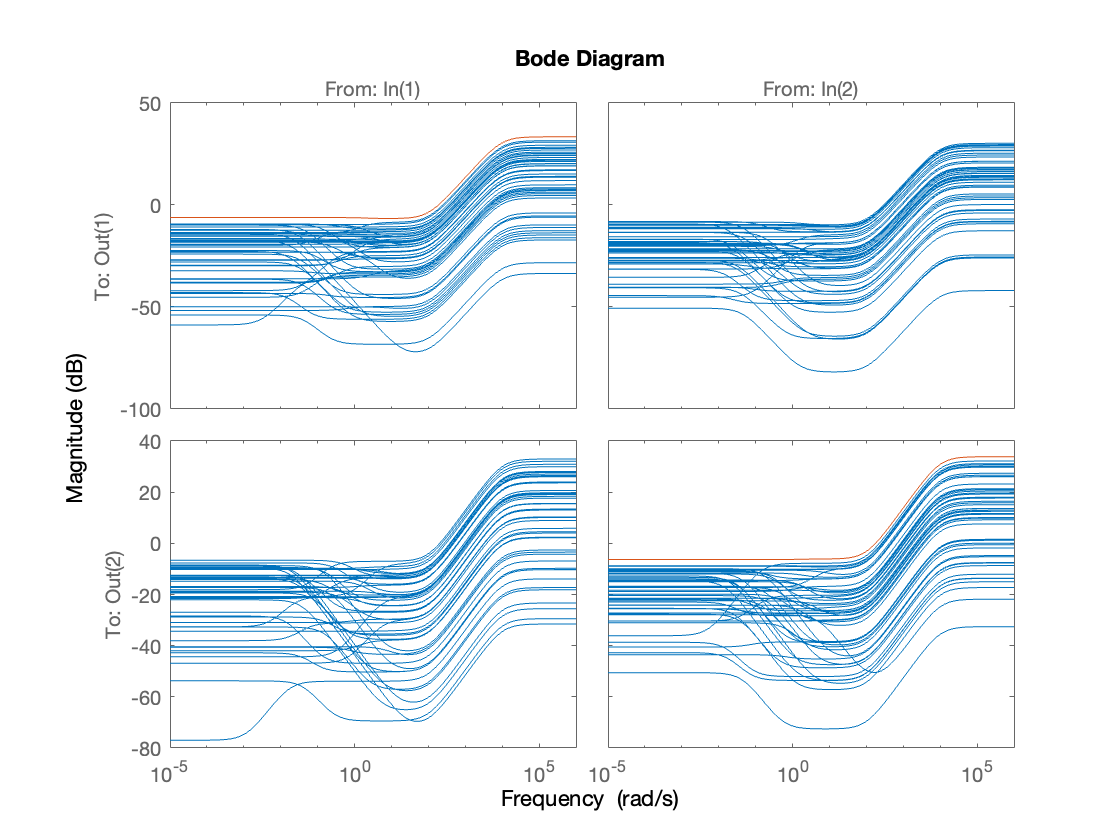

close all;
clc;
clear;
A = [-0.0226 -36.6 -18.9 -32.1; 0 -1.9 0.983 0; 0.0123 -11.7 -2.63 0; 0 0 1 0];
B = [0 0;-0.414 0;-77.8 22.4;0 0];
C = [0 57.3 0 0; 0 0 0 57.3];
D = zeros(2,2);
load('responses.mat','Gp_samples');
rsp_vec = Gp_samples; %sample
rsp_nom = tf(ss(A,B,C,D));
%rsp_vec = usample(rsp,100);  %Create 100 Monte Carlo samples of G
[P1,info_rsp] = ucover(rsp_vec,rsp_nom,[2,2]);  %Find the best 2nd order multiplicative uncertainty
% P1
W_del = info_rsp.W1;
bodemag(inv(rsp_nom)*rsp_vec-eye(2), W_del) %Gvec: 100 samples

# Q3b

Design an H∞ optimal controller considering the uncertainty. Plot the Bode magnitude of the sensitivity function for 10 samples of the uncertain plant. Do you meet robust performance specs? What about robust stability?

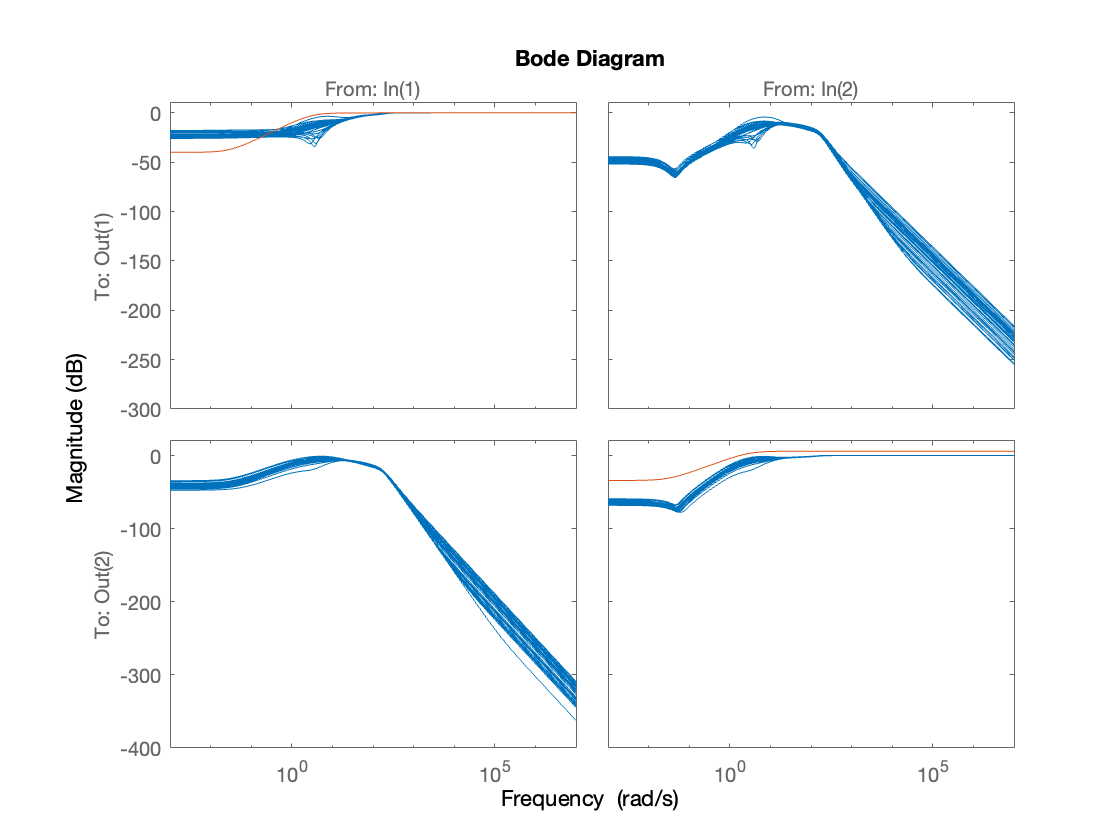

s = tf('s');
%W_del = tf(W_del);
Wp = [(s+3)/(s+0.03) 0;0 0.5*(s+3)/(s+0.03)];
Wn = [2*(s+1.28)/(s+320) 0;0 2*(s+128)/(s+320)];
P0 = rsp_nom;

systemnames = 'P0 Wp Wn W_del'; %Block name only
inputvar = '[p{2};n{2};d{2};u{2}]';
outputvar = '[W_del;Wp;n+P0+d]'; %Strangely, the system outputs are just the name
input_to_P0 = '[u+p]';
input_to_Wp = '[d+P0]';
input_to_Wn = '[n]';
input_to_W_del = '[u]';
cleanupsysic = 'yes';  %This drops all the useless variables from workspace
P = sysic;
% P = [zeros(2) zeros(2) zeros(2) W_del; Wp*rsp_nom zeros(2) Wp Wp*rsp_nom; rsp_nom Wn eye(2) rsp_nom];
[K,CL,GAM] = hinfsyn(P,2,2);
G_vec = usample(rsp_vec,10);
Svec = inv(eye(2)+G_vec*K); 
bodemag(Svec,1/Wp)

%S = 1-feedback(rsp_vec*K,1);
N = lft(P,K); 
%Check Robust Stability
% [STABMARG,WCU] = robstab(S);

The returns of this command are weird, effectively giving 1/mu as the main output.

% mu = 1/STABMARG.LowerBound
%Check Robust Perforamnce
perfmarg_inf = robgain(N,1); %wrap uncertainty 
mu_inf = 1/perfmarg_inf.LowerBound

mu_inf = 96.8558